# Training data 

More on [https://github.com/slevin48/gta](https://github.com/slevin48/gta) 

## Data access

### Get Data from dumped images

training_data_0 = imread("screenshots\training_data-2021-02-12-2\screenshots1\training_data_0.jpg")

training_data_0 = 270×480×3 uint8 array
training_data_0(:,:,1) =

   154   155   151   150   150   153   155   149   153   152   148   149   148   148   148   145   137   134   135   135   133   136   140   138   134   137   134   129   127   123   108    99   101   103   103    96   101   108   103   100   103   104   102   100   102   104   102    96    95    95    89    86    89    80    81    79    76    66    66    54    56   101   145   162   157   151   159   140    59    82    61    45   162   102   100    61    89    48    40    49    47    18    56    46    50    72   100    56    68    96    55    63    92    81    49    55    62    57    48    37    55    36    15    95    97    72    39    41    40    38    49    49    66    61    66    61    53    67    52    63    71    88    52    58    61    47    37   109   103    67    98    78    60    47   110   119   158   189   184   181   184   182   179   180   184   181    34    22    41   125   111   109    91   107    80   2

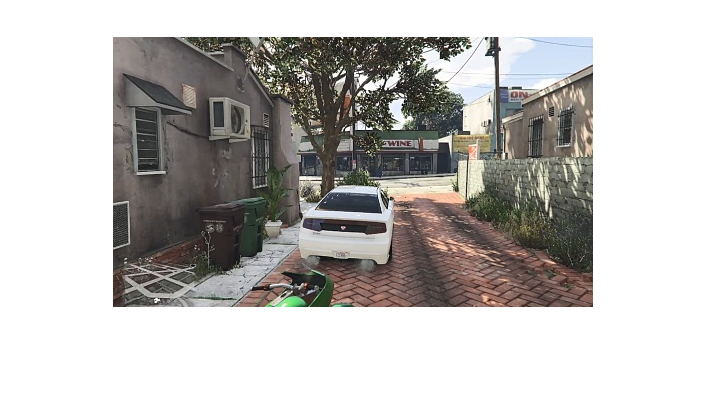

imshow(training_data_0)

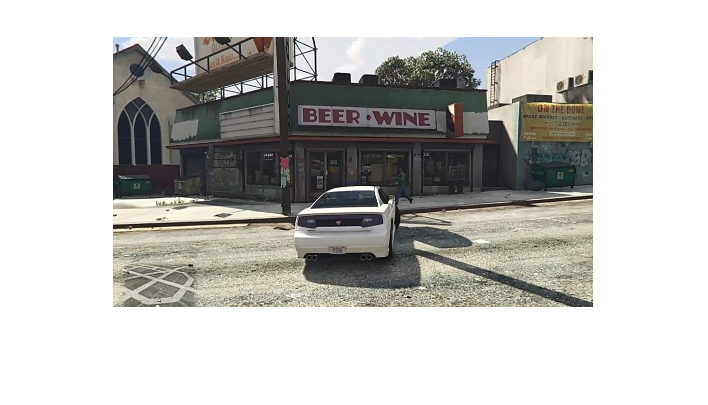

i = 198;
training_img = imread("screenshots\training_data-2021-02-12-2\screenshots1\training_data_"+string(i)+".jpg");
imshow(training_img)

k = 1;
timeline = readtable("timeline\training_data-2021-02-12-3\timeline"+string(k)+".csv")

timeline = 500×2 table
    Var1             time          
    ____    _______________________

      0     2021-02-12 20:00:06.538
      1     2021-02-12 20:00:06.568
      2     2021-02-12 20:00:06.585
      3     2021-02-12 20:00:06.602
      4     2021-02-12 20:00:06.617
      5     2021-02-12 20:00:06.637
      6     2021-02-12 20:00:06.654
      7     2021-02-12 20:00:06.686
      8     2021-02-12 20:00:06.703
      9     2021-02-12 20:00:06.719
     10     2021-02-12 20:00:06.734
     11     2021-02-12 20:00:06.752
     12     2021-02-12 20:00:06.768
     13     2021-02-12 20:00:06.784
     14     2021-02-12 20:00:06.801
     15     2021-02-12 20:00:06.818


i = 353;
training_img = imread("screenshots\training_data-2021-02-12-3\screenshots1\training_data_"+string(i)+".jpg");
timeline(i,"time").time

ans = datetime
   2021-02-12 20:00:14.407


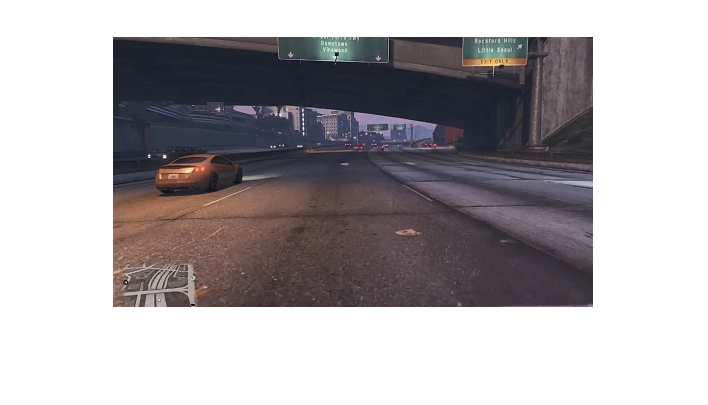

imshow(training_img)

### Get controller inputs

We have 2 options:

- Get the controller input directly with [https://github.com/komefai/PS4Macro](https://github.com/komefai/PS4Macro)

- Map the command to the Keyboard with [https://github.com/starshinata/PS4-Keyboard-and-Mouse-Adapter](https://github.com/starshinata/PS4-Keyboard-and-Mouse-Adapter)

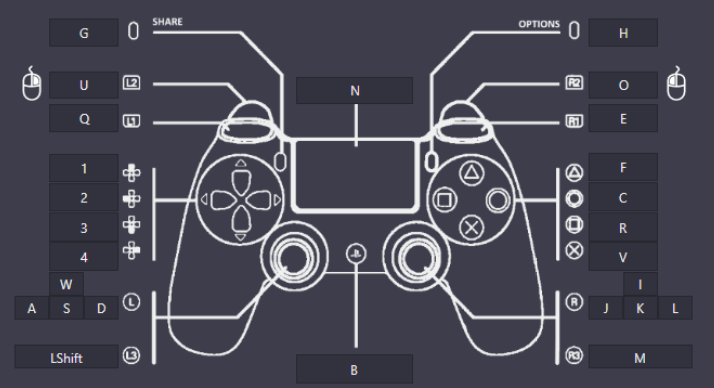

The folder `ps4_macro `contains the controller record and python functions:

py.os.chdir("ps4_macro");
% py.os.chdir("..")
cwd = py.os.getcwd()

cwd =   Python str with no properties.

    C:\Users\ydebray\Downloads\gta\ps4_macro


`PS4_control.py` provides 2 functions to: 

- **read** XML controller file as DataFrame, 

- **save** it as Excel file

df = py.PS4_control.read_controller("2021-02-12-3.xml");
py.PS4_control.save_controller(df,"2021-02-12-3.xlsx")

py.os.chdir("..")
% py.os.getcwd()

% Specify column names and types
opts = spreadsheetImportOptions("NumVariables", 33);
opts.DataRange = "B2";
opts.VariableNames = ["ReportTimeStamp", "LX", "LY", "RX", "RY", "L2", "R2", "Triangle", "Circle", "Cross", "Square", "DPad_Up", "DPad_Down", "DPad_Left", "DPad_Right", "L1", "R1", "Share", "Options", "L3", "R3", "PS", "TouchButton", "TouchPacketCounter", "FrameCounter", "Battery", "IsCharging", "AccelX", "AccelY", "AccelZ", "GyroX", "GyroY", "GyroZ"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "double", "double", "double", "categorical", "double", "double", "double", "double", "double", "double"];

T = readtable("ps4_macro/2021-02-12-3.xlsx",opts);
T.ReportTimeStamp = datetime(T.ReportTimeStamp,"InputFormat","uuuu-MM-dd'T'HH:mm:ss.SSSSSSS'Z'");
T.ReportTimeStamp.Format = 'MMM dd, yyyy HH:mm:ss.SSS'

T = 14565×33 table
         ReportTimeStamp         LX     LY     RX     RY     L2    R2    Triangle    Circle    Cross    Square    DPad_Up    DPad_Down    DPad_Left    DPad_Right     L1       R1      Share    Options     L3       R3       PS      TouchButton    TouchPacketCounter    FrameCounter    Battery    IsCharging    AccelX    AccelY    AccelZ    GyroX    GyroY    GyroZ
    _________________________    

The conversion does keep the fractional seconds. However, by default `datetime` arrays do not *display* fractional seconds. To display them, specify either the `'Format'` name-value pair or the `Format` property.

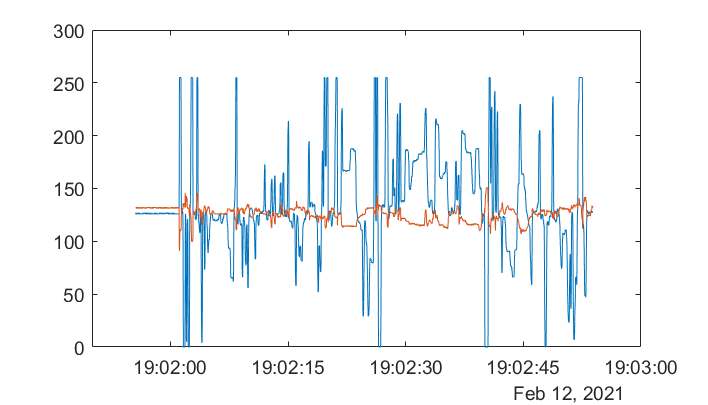

plot(T.ReportTimeStamp,[T.LX,T.LY])

The ReportTimeStamp has an offset with the timestamp from the video record

**Go further: **[Synchronizing Time-Series Data Using MATLAB - YouTube](https://www.youtube.com/watch?v=ltheBeYpCxs&ab_channel=MATLAB)

### Get keyboard inputs

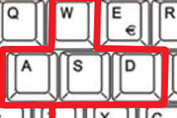

**/!\**** Q instead of A for French keyboard here!!!**

T = readtable("keyboard/training_data-1.csv");
T = renamevars(T,"Var1","ID")

T = 500×10 table
    ID    W    S    Q    D    WQ    WD    SQ    SD    NOKEY
    __    _    _    _    _    __    __    __    __    _____

     0    0    0    0    0    0     0     0     0       1  
     1    0    0    0    0    0     0     0     0       1  
     2    0    0    0    0    0     0     0     0       1  
     3    0    0    0    0    0     0     0     0       1  
     4    0    0    0    0    0     0     0     0       1  
     5    0    0    0    0    0     0     0     0       1  
     6    0    0    0    0    0     0     0     0       1  
     7    0    0    0    0    0     0     0     0       1  
     8    0    0    0    0    0     0     

T(T.D == 1,:) % Turning right

ans = 18×10 table
    ID     W    S    Q    D    WQ    WD    SQ    SD    NOKEY
    ___    _    _    _    _    __    __    __    __    _____

    212    0    0    0    1    0     0     0     0       0  
    213    0    0    0    1    0     0     0     0       0  
    214    0    0    0    1    0     0     0     0       0  
    215    0    0    0    1    0     0     0     0       0  
    216    0    0    0    1    0     0     0     0       0  
    359    0    0    0    1    0     0     0     0       0  
    360    0    0    0    1    0     0     0     0       0  
    361    0    0    0    1    0     0     0     0       0  
    362    0    0    0    1    

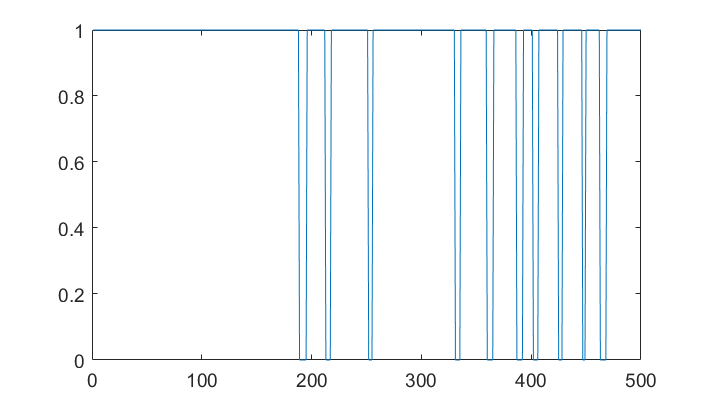

plot(T.NOKEY)

### Get data from Numpy directly

pyenv

npfiles = dir("training_data\training_data-2021-02-12-3");

npfiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


npfiles = npfiles(3:end,:)

ans = 7

length(npfiles)

npfile = 3;
% npdata = py.numpy.load("training_data\training_data-"+string(nb_train)+".npy")
npdata = py.training_data.load_data("training_data\training_data-"+string(npfile)+".npy")

npdata =   Python list with no properties.

    [array([[[216, 200, 190],
            [216, 200, 190],
            [216, 200, 190],
            ...,
            [215, 202, 190],
            [215, 202, 190],
            [215, 202, 190]],
    
           [[216, 200, 190],
            [216, 200, 190],
            [216, 200, 190],
            ...,
            [215, 202, 190],
            [214, 202, 189],
            [214, 201, 188]],
    
           [[218, 201, 192],
            [217, 200, 190],
            [217, 200, 191],
            ...,
            [213, 200, 188],
            [214, 201, 188],
            [214, 201, 188]],
    
           ...,
    
           [[ 83, 110, 120],
            [ 84, 112, 121],
            [ 83, 111, 120],
            ...,
            [ 52,  81,  92],
            [ 45,  70,  82],
            [ 47,  71,  84]],
    
           [[ 79, 106, 116],
            [ 87, 114, 123],
            [ 82, 110, 1

mdata = cell(npdata)

mdata = 1×500 cell array
  Columns 1 through 384

    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.numpy.ndarray}    {1×1 py.nu

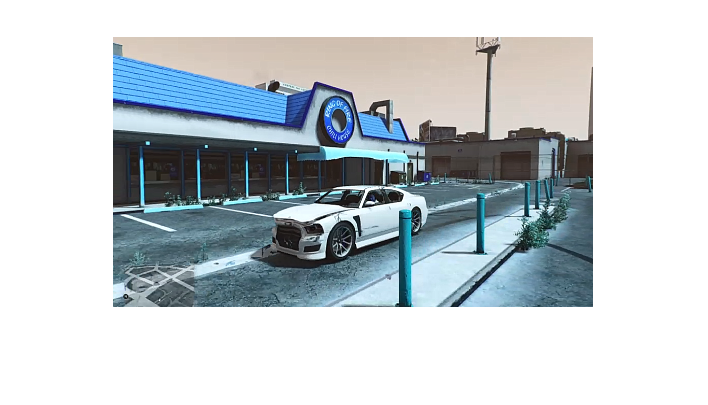

imshow(uint8(mdata{1}))

### Specify data

k = 5;
dataFolder = "screenshots\training_data-2021-02-12-4\screenshots"+string(k);
% renameImages(dataFolder); % only need to be run once
imds = imageDatastore(dataFolder);

## Modelling

### Aside : what does a pre-trained ACF detector give us ?

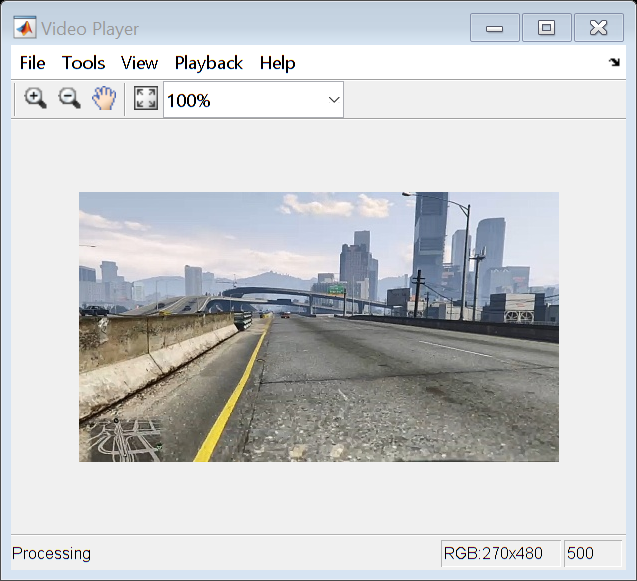

detector = vehicleDetectorACF('front-rear-view');
vp = vision.VideoPlayer ;

reset(imds);
reset(vp)
while hasdata( imds )
    I = read( imds );
    [bboxes,scores] = detect(detector,I);
    if ~isempty( bboxes )
        I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
    end
    step( vp, I )
    drawnow
end

### Deep Learning

Read in response data and reformat 

T = readtable("training_data-3.csv");
numPoints = size(T, 1);
right = T.D ;
left = T.Q ;
straight = double(~( logical( right) | logical(left) ));
labels = straight + 2*left + 3*right;
imds.Labels = categorical(labels);

Resize input data to match network architecture

outputSize = [227 227];
auimds = augmentedImageDatastore(outputSize, imds);

### Use Deep Network Designer to do transfer learning

In this case, using AlexNet for transfer learning does not work as the training is not converging. We need more data, and also to revisit how the problem is formulated. 

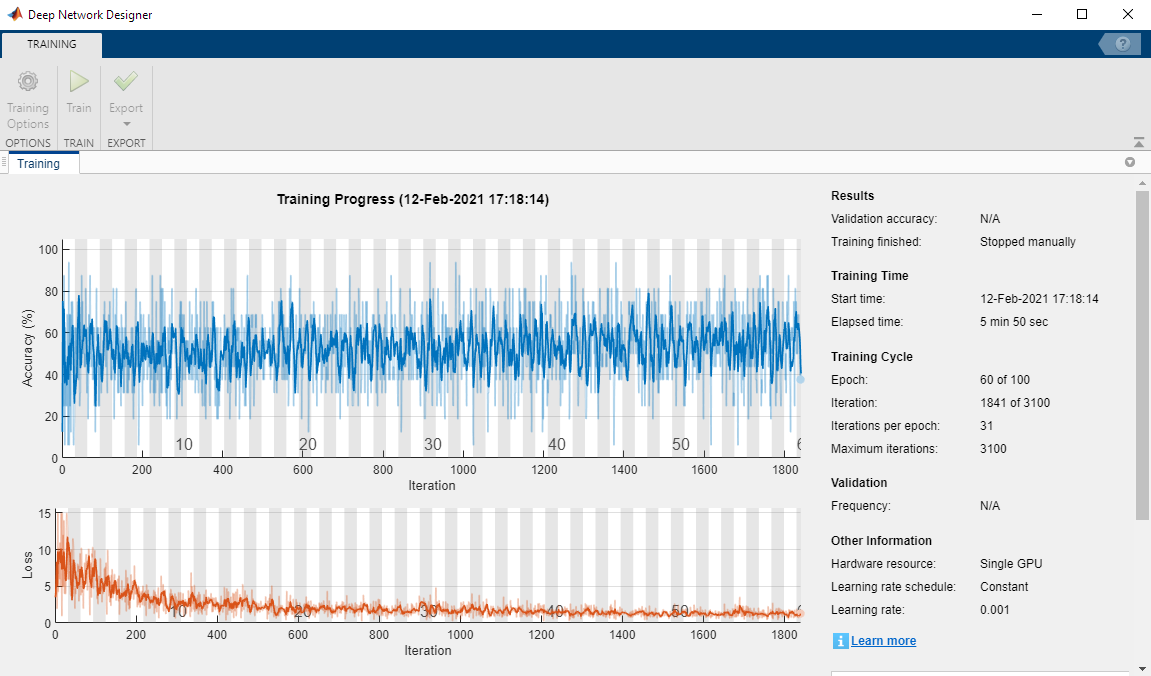

### Helper function

function renameImages( dataFolder )

D = dir(dataFolder);
nameRoot = "training_data_";
for i = 1:numel(D)
    if D(i).isdir == 0
        
        I = imread(fullfile(dataFolder, D(i).name));
        [~,filename,ext] = fileparts(D(i).name);
        nameLength = length( filename );
        if nameLength == 17
            continue;
        else
            if nameLength == 15
                imNumber = ["00" + filename(15)] ;
            elseif nameLength == 16
                imNumber = ["0" + filename(15:16)];                
            end
            newFilename = [nameRoot + imNumber + ext];
            imwrite(I, fullfile(dataFolder, newFilename));
            delete(fullfile(dataFolder, D(i).name));
        end
    end
end

end